executionEnvironment = 'gpu';
dataFolder = "D:\F DIV\F12\dataset";

ads = audioDatastore(dataFolder, 'IncludeSubfolders', true);
% Extract the speaker label from the file path
ads.Labels = folders2labels(ads);

% Create an audioDatastore object to access the LIBRISPEECH audio data in Train-conv
trainConvFolder = fullfile(dataFolder, 'Train-conv');
adsTrain = audioDatastore(trainConvFolder, 'IncludeSubfolders', true);
adsTrain.Labels = folders2labels(adsTrain);

% Create an audioDatastore object to access the LIBRISPEECH audio data in Test-read
testReadFolder = fullfile(dataFolder, 'Test-read');
adsTest = audioDatastore(testReadFolder, 'IncludeSubfolders', true);
adsTest.Labels = folders2labels(adsTest);

Data

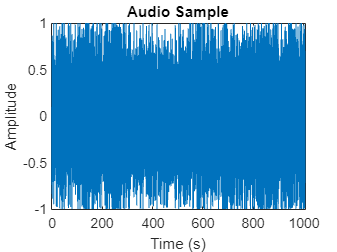

% Data speedupExample
speedupExample = false;
if speedupExample
    % Select only 20 files from Train-conv
    numFilesTrain = 20;
    adsTrain = subset(adsTrain, 1:numFilesTrain);
    
    % Select only 20 files from Test-read
    numFilesTest = 20;
    adsTest = subset(adsTest, 1:numFilesTest);
    
    % Use 80% of files from Train-conv for training
    trainPercentage = 0.8;
    adsTrain = splitEachLabel(adsTrain, trainPercentage);
    
    
    % Use 20% of files from Test-read for testing
    %testPercentage = 0.2;
    %adsTest = splitEachLabel(adsTest, testPercentage);
end

numFilesTrain = 10;
adsTrain = subset(adsTrain, 1:numFilesTrain);

numFilesTest = 10;
adsTest = subset(adsTest, 1:numFilesTest);



[audioIn, dsInfoTrain] = read(adsTrain);
Fs = dsInfoTrain.SampleRate;


%sound(audioIn,Fs)

t = (1/Fs)*(0:length(audioIn)-1);

plot(t,audioIn)
title("Audio Sample")
xlabel("Time (s)")
ylabel("Amplitude")
grid on

reset(adsTrain)
reset(adsTest)

    DATA PREPROCE SSING

frameDuration = 200e-3;
overlapDuration = 40e-3;
frameLength = floor(Fs*frameDuration); 
overlapLength = round(Fs*overlapDuration);

pFlag = ~isempty(ver("parallel"));

adsTrainTransform = transform(adsTrain,@(x){preprocessAudioData(x,frameLength,overlapLength,Fs)});
XTrain = readall(adsTrainTransform,UseParallel=pFlag);

Starting parallel pool (parpool) using the 'Processes' profile ...
Connected to parallel pool with 64 workers.


chunksPerFile = cellfun(@(x)size(x,4),XTrain);
TTrain = repelem(adsTrain.Labels,chunksPerFile,1);
XTrain = cat(4,XTrain{:});

adsTestTransform = transform(adsTest,@(x){preprocessAudioData(x,frameLength,overlapLength,Fs)});
XTest = readall(adsTestTransform,UseParallel=true);
chunksPerFile = cellfun(@(x)size(x,4),XTest);
TTest = repelem(adsTest.Labels,chunksPerFile,1);
XTest = cat(4,XTest{:});

CNN

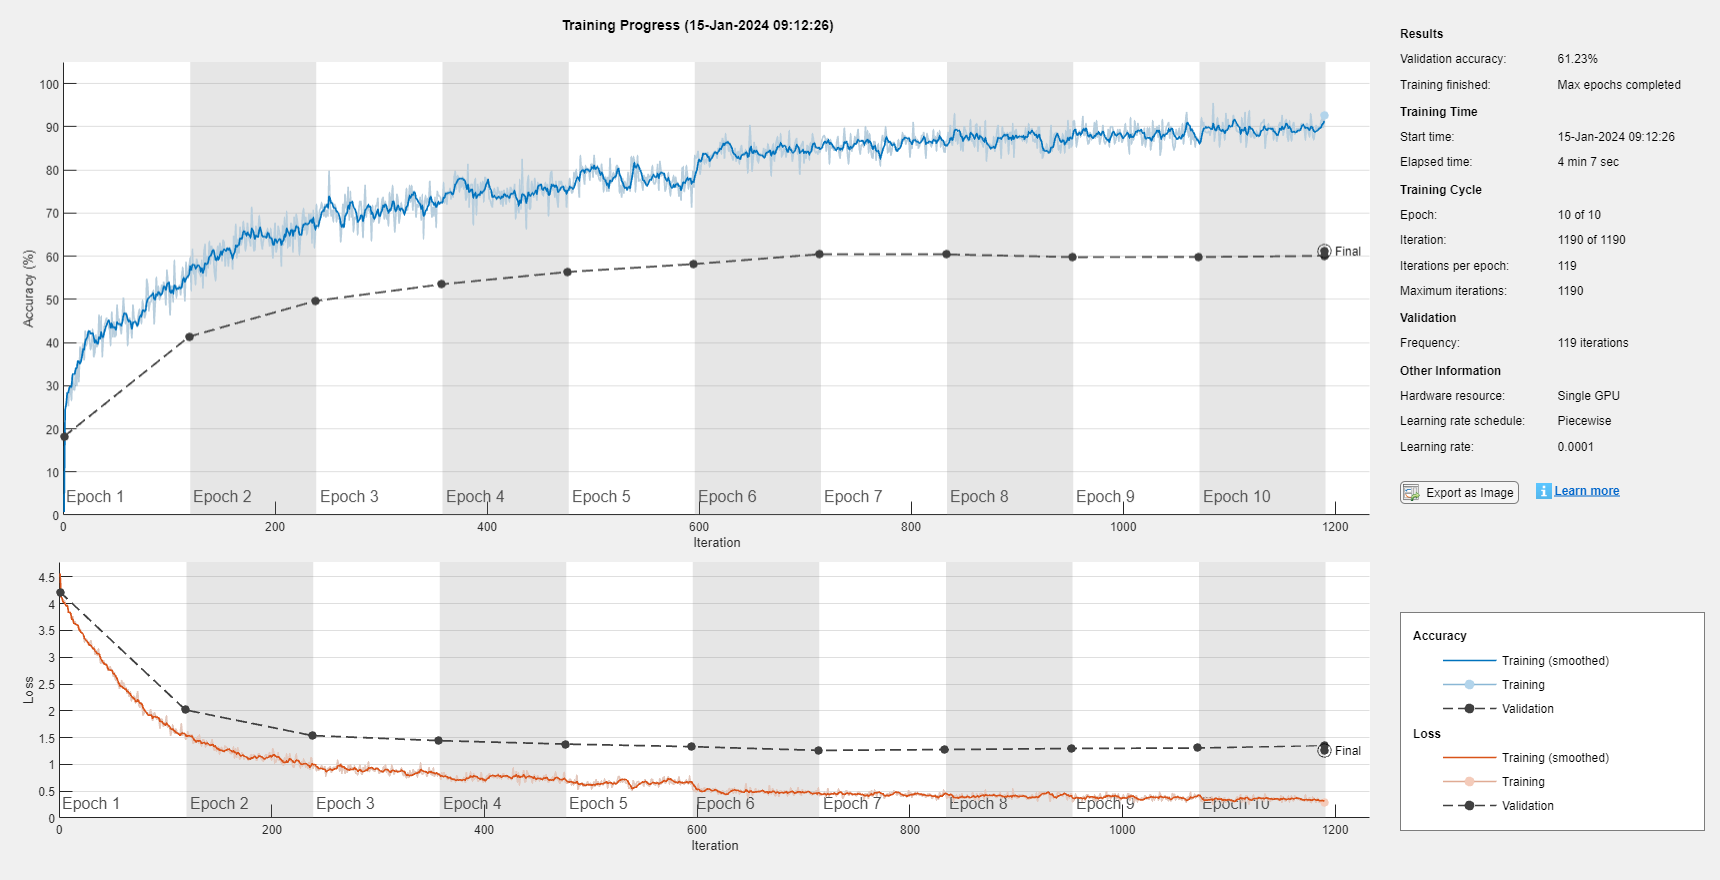

numFilters = 120;
filterLength = 251;
numSpeakers = numel(unique(removecats(ads.Labels)));

layers = [ 
    imageInputLayer([1 frameLength 1])
    convolution2dLayer([1 filterLength], numFilters)
    batchNormalizationLayer
    leakyReluLayer(0.2)
    maxPooling2dLayer([1 3])
    
    convolution2dLayer([1 3], 30)
    batchNormalizationLayer
    leakyReluLayer(0.2)
    maxPooling2dLayer([1 3])
    
    convolution2dLayer([1 3], 30)
    batchNormalizationLayer
    leakyReluLayer(0.2)
    maxPooling2dLayer([1 3])

    fullyConnectedLayer(128)
    batchNormalizationLayer
    leakyReluLayer(0.2)
    
    fullyConnectedLayer(64)
    batchNormalizationLayer
    leakyReluLayer(0.2)

    fullyConnectedLayer(32)
    batchNormalizationLayer
    leakyReluLayer(0.2)

    fullyConnectedLayer(numSpeakers) % Adjusted the number of neurons to match the number of classes
    softmaxLayer
    classificationLayer];

analyzeNetwork(layers)

numEpochs = 10;
miniBatchSize = 300;
validationFrequency = floor(numel(TTrain)/miniBatchSize);

options = trainingOptions("adam", ...
    Shuffle="every-epoch", ...
    MiniBatchSize=miniBatchSize, ...
    Plots="training-progress", ...
    Verbose=false, ...
    MaxEpochs=numEpochs, ...
    ValidationData={XTest, categorical(TTest)}, ...
    ValidationFrequency=validationFrequency, ...
    InitialLearnRate=0.001, ... % Adjust the initial learning rate
    LearnRateSchedule='piecewise', ...
    LearnRateDropFactor=0.1, ...
    LearnRateDropPeriod=5); % Adjust the drop factor and period


[convNet, convNetInfo] = trainNetwork(XTrain, TTrain, layers, options);

Frequency response

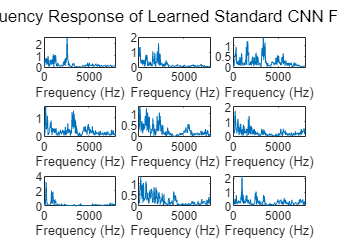

F = squeeze(convNet.Layers(2,1).Weights);
H = zeros(size(F));
Freq = zeros(size(F));

for ii = 1:size(F,2)
   [h,f] = freqz(F(:,ii),1,251,Fs);
    H(:,ii) = abs(h);
    Freq(:,ii) = f;
end
idx = linspace(1,size(F,2),9);
idx = round(idx);

figure
for jj = 1:9
   subplot(3,3,jj)
   plot(Freq(:,idx(jj)),H(:,idx(jj)))
   sgtitle("Frequency Response of Learned Standard CNN Filters")
   xlabel("Frequency (Hz)")
end

Sincnet

numFilters = 150;
filterLength = 251;
numChannels = 1; 
name = "sinc";

sNL = sincNetLayer(numFilters,filterLength,Fs,numChannels,name)

sNL =   sincNetLayer with properties:

                 Name: 'sinc'

   Learnable Parameters
    FilterFrequencies: [0.0019 0.0032 0.0040 0.0048 0.0056 0.0064 0.0072 0.0081 0.0089 0.0098 0.0107 0.0116 0.0125 0.0134 0.0143 0.0153 0.0163 0.0173 0.0183 0.0193 0.0203 0.0214 0.0225 0.0236 0.0247 0.0258 0.0269 0.0281 0.0293 0.0305 … ] (1×150 double)
     FilterBandwidths: [0.0021 0.0016 0.0016 0.0016 0.0016 0.0017 0.0017 0.0017 0.0018 0.0018 0.0018 0.0018 0.0019 0.0019 0.0019 0.0020 0.0020 0.0020 0.0021 0.0021 0.0021 0.0022 0.0022 0.0022 0.0023 0.0023 0.0024 0.0024 0.0024 0.0025 … ] (1×150 double)

   State Parameters
    No properties.

  Show all properties


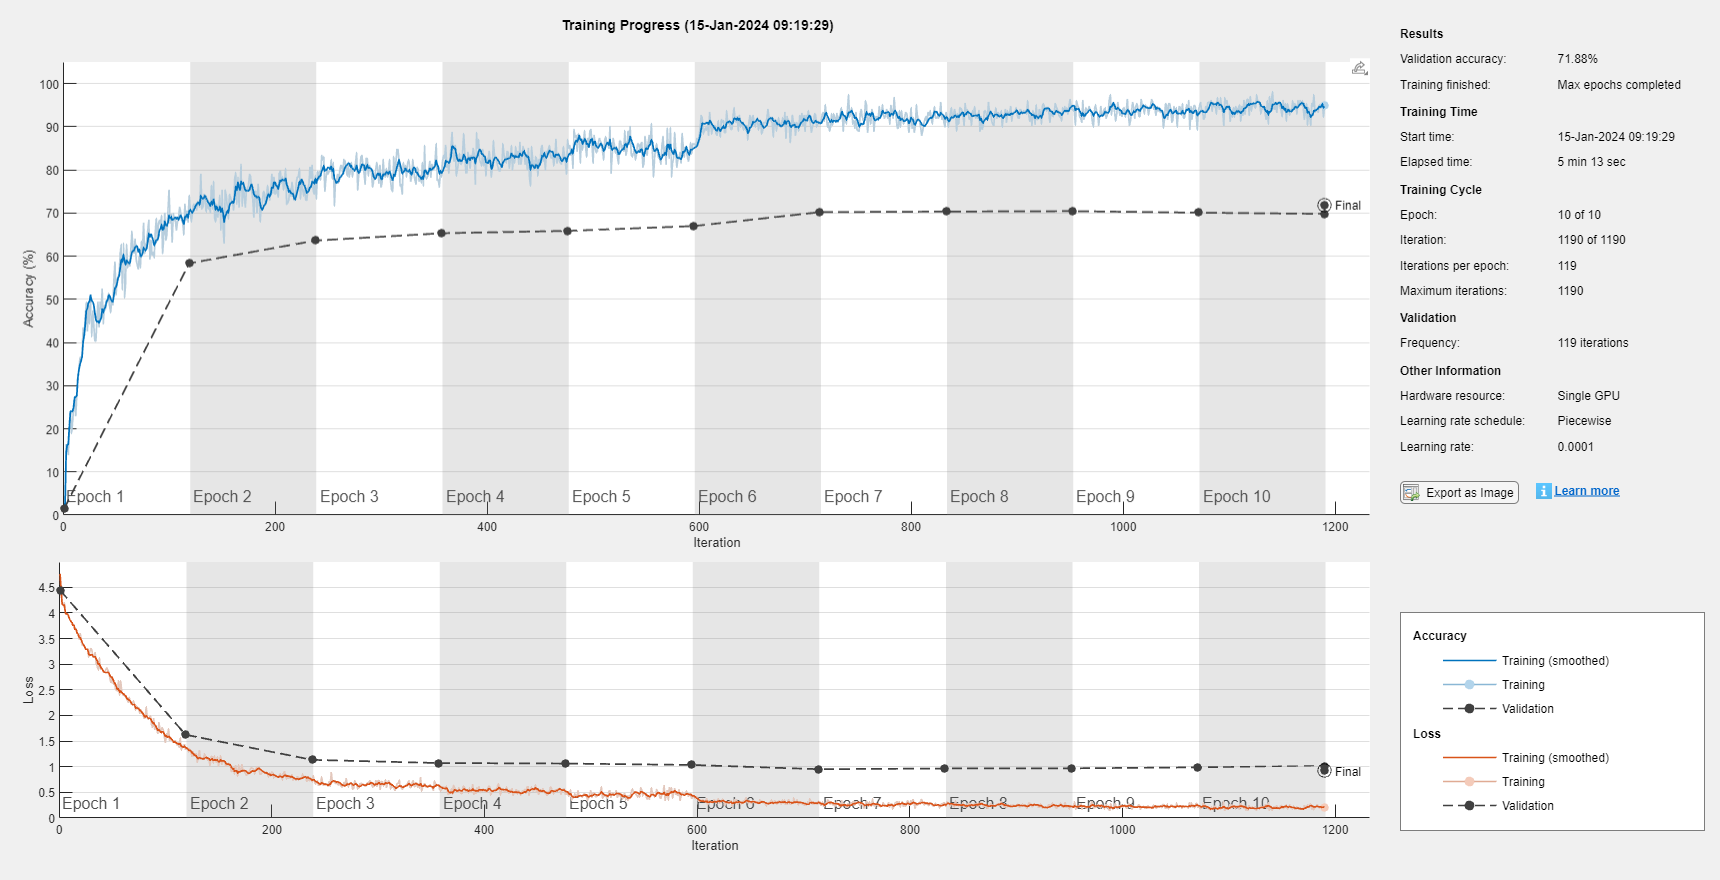


layers(2) = sNL;

[sincNet,sincNetInfo] = trainNetwork(XTrain,TTrain,layers,options);

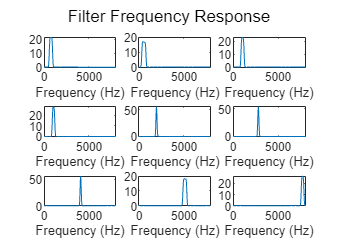


figure
plotNFilters(sincNet.Layers(2),9)

Prediction

epoch = linspace(0,numEpochs,numel(sincNetInfo.ValidationAccuracy(~isnan(sincNetInfo.ValidationAccuracy))));
epoch = [epoch,numEpochs];

sinc_valAcc = [sincNetInfo.ValidationAccuracy(~isnan(sincNetInfo.ValidationAccuracy)),...
    sincNetInfo.FinalValidationAccuracy];

figure
plot(epoch,sinc_valAcc,"-*",MarkerSize=4)
ylabel("Frame-Level Accuracy (Test Set)")
xlabel("Epoch")
xlim([0 numEpochs+0.3])
title("Frame-Level Accuracy Versus Epoch")
legend("sincNet","constantSincLayer","conv2dLayer",Location="southeast")

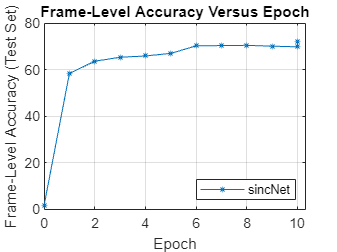

grid on

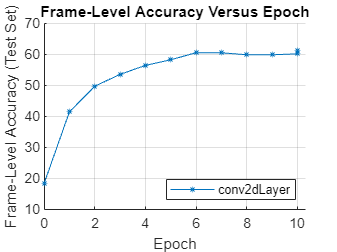

epoch = linspace(0,numEpochs,numel(sincNetInfo.ValidationAccuracy(~isnan(sincNetInfo.ValidationAccuracy))));
epoch = [epoch,numEpochs];

conv_valAcc = [convNetInfo.ValidationAccuracy(~isnan(convNetInfo.ValidationAccuracy)),...
    convNetInfo.FinalValidationAccuracy];

figure
%plot(epoch,sinc_valAcc,"-*",MarkerSize=4)
hold on
%plot(epoch,const_sinc_valAcc,"-*",MarkerSize=4)
plot(epoch,conv_valAcc,"-*",MarkerSize=4)
ylabel("Frame-Level Accuracy (Test Set)")
xlabel("Epoch")
xlim([0 numEpochs+0.3])
title("Frame-Level Accuracy Versus Epoch")
legend("conv2dLayer",Location="southeast")
grid on

NetworkType = ["Standard CNN";"SincNet Layer"];
Accuracy = [convNetInfo.FinalValidationAccuracy;sincNetInfo.FinalValidationAccuracy];

resultsSummary = table(NetworkType,Accuracy)

resultsSummary = 2×2 table
      NetworkType      Accuracy
    _______________    ________

    "Standard CNN"      61.229 
    "SincNet Layer"     71.883 


function xp = preprocessAudioData(x,frameLength,overlapLength,Fs)

speechIdx = detectSpeech(x,Fs);
xp = zeros(1,frameLength,1,0);

for ii = 1:size(speechIdx,1)
    % Isolate speech segment
    audioChunk = x(speechIdx(ii,1):speechIdx(ii,2));

    % Split into 200 ms chunks
    audioChunk = buffer(audioChunk,frameLength,overlapLength);
    audioChunk = reshape(audioChunk,1,frameLength,1,size(audioChunk,2));

    % Concatenate with existing audio
    xp = cat(4,xp,audioChunk);
end
end

